% SECTION 1: This section handles manual input of the truss in line with
% the requirements outlined in the Preliminary Design Manual. 

C = [[0, 1, 1]; [1, 0, 1]; [1, 1, 0]]

C =      0     1     1
     1     0     1
     1     1     0


Sx = [[0, 0, 0]; [1, 0, 0]; [0, 0, 0]]

Sx =      0     0     0
     1     0     0
     0     0     0


Sy = [[0, 0, 0]; [0, 1, 0]; [0, 0, 1]]

Sy =      0     0     0
     0     1     0
     0     0     1


L = [5; 4; 0; 0; 0; 0]

L =      5
     4
     0
     0
     0
     0


X = [0, 0, 1];
Y = [1, 0, 0];

% SECTION 2: This section handles the conversion of the manual input (C,
% Sx, Sy, L, X, and Y matrices) 

% Run this section if you ran section 1. 

[row, col] = find(C == 1)

row =      2
     3
     1
     3
     1
     2


col =      1
     1
     2
     2
     3
     3


connections = [row(row<col), col(row<col)];
clear nodes 
alphabet = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

alphabet = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

for i = 1:size(X, 2)
    nodes(i).label = alphabet(i);
    nodes(i).pos = [X(i), Y(i)];
    nodes(i).external_force = [-L(2*i - 1), -L(2*i)];
    nodes(i).reactions = [
        repmat([1 0], nnz(Sx(i,:)), 1);
        repmat([0 1], nnz(Sy(i,:)), 1)
    ];
end 

nodes 

nodes = 1×3 struct array with fields:
    label
    pos
    external_force
    reactions


% SECTION 3: This section of the code initializes the truss structure to be analyzed
% in the interpretable form. Note that the external force defaults to [0,
% 0] and reactions defaults to none. 

% DO NOT RUN this section if you ran sections 1 and 2. 

% An example truss is provided here. Scripts for setup are also contained
% in the GitHub. Replace this code with that. 

clear nodes 

nodes(1).label = "A";
nodes(1).pos = [0, 0];
nodes(1).external_force = [0, 0];
nodes(1).reactions = [[1, 0]; [0, 1]];

nodes(2).label = "B";
nodes(2).pos = [9, 0];
nodes(2).external_force = [0, 0];
nodes(2).reactions = [[]];

nodes(3).label = "C";
nodes(3).pos = [20, 0];
nodes(3).external_force = [0, -1];
nodes(3).reactions = [[]];

nodes(4).label = "D";
nodes(4).pos = [34, 0];
nodes(4).external_force = [0, 0];
nodes(4).reactions = [[0, 1]];

nodes(5).label = "E"

nodes = 1×5 struct array with fields:
    label
    pos
    external_force
    reactions


nodes(5).pos = [4.5, 7.79]; 
nodes(5).external_force = [0, 0];
nodes(5).reactions = [[]]; 

nodes(6).label = "F"

nodes = 1×6 struct array with fields:
    label
    pos
    external_force
    reactions


nodes(6).pos = [14.5, 9.52];
nodes(6).external_force = [0, 0];
nodes(6).reactions = [[]];

nodes(7).label = "G"

nodes = 1×7 struct array with fields:
    label
    pos
    external_force
    reactions


nodes(7).pos = [27, 12.12];
nodes(7).external_force = [0, 0];
nodes(7).reactions = [[0, 0]];

str_connections = ["AE", "EF", "FG", "GD", "CD", "BC", "AB", "EB", "BF", "CF", "CG"]

str_connections = 1×11 string array
    "AE"    "EF"    "FG"    "GD"    "CD"    "BC"    "AB"    "EB"    "BF"    "CF"    "CG"


% SECTION 4: Pre-processing of interpretable (intermediate) truss entry format. 
% RUN this section if you ran section 3. 

for i = 1:length(nodes)
    if ~isfield(nodes(i), "external_force") || isempty(nodes(i).external_force)
        nodes(i).external_force = [0, 0];
    end

    if ~isfield(nodes(i), "reactions") || isempty(nodes(i).reactions)
        nodes(i).reactions = [];
    end
end

nodeLabels = string({nodes.label});

connections_idx = zeros(length(str_connections), 2);

for k = 1:length(str_connections)

    member = str_connections(k);

    label1 = extractBetween(member, 1, 1);
    label2 = extractBetween(member, 2, 2);

    connections_idx(k,1) = find(nodeLabels == label1);
    connections_idx(k,2) = find(nodeLabels == label2);

end

connections = connections_idx;

% SECTION 5: This section does the bulk of the truss analysis. 
% Run this section no matter what, as it is the central component of the
% analysis! 

cost = 0;
cost_per_inch = 1;

N = length(nodes);

b = zeros(2*N,1);
n_loading = 0; 
primary_load_index = 0; % meaningless if there's more than one...
for i = 1:N
    if ~(isequal(nodes(i).external_force, [0, 0]))
        n_loading = n_loading + 1;
        primary_load_index = i
    end 
    b(2*i - 1) = -nodes(i).external_force(1);
    b(2*i)     = -nodes(i).external_force(2);
end

primary_load_index = 3



mat = zeros(2*N, 2*N);

% This section looks at the joints and updates the matrix accordingly 

M = size(connections, 1);

buckle_loads = zeros(M, 1); % At what compressive load will it buckle?

for m = 1:M;
    
    i = connections(m, 1);
    j = connections(m, 2);
    vec = nodes(j).pos - nodes(i).pos;

    cost = cost + cost_per_inch * norm(vec);
    buckle_loads(m) = 2219 / (norm(vec) ^ 1.89);

    vec = vec / norm(vec);
    mat(2*i - 1, m) = vec(1);
    mat(2*i, m) = vec(2);
    mat(2*j - 1, m) = -vec(1);
    mat(2*j, m) = -vec(2);
    labels(m) = "Member " + nodes(i).label + "" + nodes(j).label;
end;
% This section looks at the reaction forces 

m = M;
for i = 1:N; 
    r = nodes(i).reactions;
    if ~ (isempty(r));
        m = m + 1;

        label = "Reaction force on " + nodes(i).label;
        
        if isequal(r(1, :), [1, 0])
            direction = " in x-direction";
        elseif isequal(r(1, :), [0, 1])
            direction = " in y-direction";
        else 
            direction = " in direction [" + join(string(r(1,:)), ", ") + "]";
        end 

        labels(m) = label + direction;

        mat(2*i - 1, m) = r(1, 1); 
        mat(2*i, m) = r(1, 2);
    end
    if size(r, 1) == 2;
        m = m + 1;

        label = "Reaction force on " + nodes(i).label;
        
        if isequal(r(2, :), [1, 0])
            direction = " in x-direction";
        elseif isequal(r(2, :), [0, 1])
            direction = " in y-direction";
        else 
            direction = " in direction [" + join(string(r(2,:)), ", ") + "]";
        end 

        labels(m) = label + direction;

        mat(2*i - 1, m) = r(2, 1); 
        mat(2*i, m) = r(2, 2);
    end
end;

cost_per_node = 10 

cost_per_node = 10


cost = cost + cost_per_node * N

cost = 194.8903

x = mat\b

x =    -0.4755
   -0.4389
   -0.7888
   -0.6793
    0.3397
    0.6272
    0.2379
    0.3891
   -0.3891
    0.2900
    0.8648
    0.0000
    0.4118
    0.5882
         0


% if m == 2*N; 
%     disp("Truss is statically determinate!")
% else; 
%     disp("Truss is statically indeterminate!")
% end; 

% SECTION 6: THIS SECTION analyzes buckling and failure conditions. Part of
% it analyzes the buckling in a probabilistic manner. This assumes that
% members buckle at 2219 * L ^ -1.89 oz. 
% Thus, only run this section if its for an EK301S acryllic truss! 

if n_loading == 1

    % Compression forces only (member forces are x(1:M))
    member_forces = max(0, -x(1:M));

    % Critical applied load for each member
    req = Inf(M,1);

    compressive = member_forces > 1e-8;
    req(compressive) = buckle_loads(compressive) ./ member_forces(compressive);

    % Deterministic result
    [minValue, minIndex] = min(req);

    current_load = norm(nodes(primary_load_index).external_force);

    fprintf('\n%-30s %s\n', ...
        "Member which Buckles First:", labels(minIndex));
    uncertainty = 0.15 * buckle_loads(minIndex);

    fprintf('%-30s %8.3f ± %8.3f oz\n', ...
    "Buckling Strength:", buckle_loads(minIndex), uncertainty);
    fprintf('%-30s %8.3f ± %8.3f oz\n', ...
        "Maximum Supportable Load:", current_load * minValue, current_load * minValue * 0.15);
    fprintf('%-30s %8.3f oz/$\n', ...
        "Theoretical Load/Cost Ratio:", current_load * minValue / cost);

    %----------------------------------------------------------
    % Probabilistic analysis
    %----------------------------------------------------------

    % Mean critical loads
    mu = req(compressive);

    % Assume 15% coefficient of variation
    sigma = 0.15 * mu;

    labels_prob = labels(compressive);

    nProb = length(mu);

    prob = zeros(nProb,1);

    for i = 1:nProb

        integrand = @(x) arrayfun(@(t) ...
            normpdf(t, mu(i), sigma(i)) .* ...
            prod(1 - normcdf( ...
                t, ...
                mu([1:i-1 i+1:end]), ...
                sigma([1:i-1 i+1:end]))), ...
            x);

        prob(i) = integral(integrand,-Inf,Inf);

    end

    % Expand back to all members
    prob_full = zeros(M,1);
    prob_full(compressive) = prob;

    fprintf('\nProbability Each Member Buckles First\n');
    fprintf('--------------------------------------\n');

    for i = 1:M
        fprintf('%-30s %.5f\n', labels(i), prob_full(i));
    end

    fprintf('\nSum of probabilities = %.6f\n', sum(prob_full));

end


Member which Buckles First:    Member GD


Buckling Strength:               15.142 ±    2.271 oz


Maximum Supportable Load:        22.291 ±    3.344 oz


Theoretical Load/Cost Ratio:      0.114 oz/$



Probability Each Member Buckles First


--------------------------------------


Member AE                      0.00000
Member EF                      0.00001
Member FG                      0.45453
Member GD                      0.54545
Member CD                      0.00000
Member BC                      0.00000
Member AB                      0.00000
Member EB                      0.00000
Member BF                      0.00001
Member CF                      0.00000
Member CG                      0.00000



Sum of probabilities = 1.000000


% SECTION 7: Prints the results of section 5. 

disp('EK301S; Shaun Ng, Tejonanditha Kolati, Andrei Leshchiner, Yua Esteban; 07/05/2026.')

EK301S; Shaun Ng, Tejonanditha Kolati, Andrei Leshchiner, Yua Esteban; 07/05/2026.


disp('LOADING CONDITIONS:')

LOADING CONDITIONS:


for i = 1:N
    if ~(nodes(i).external_force(1) == 0 & nodes(i).external_force(2) == 0)
        fprintf('Node %-2s: Fx = %8.3f, Fy = %8.3f', ...
            nodes(i).label, ...
            nodes(i).external_force(1), ...
            nodes(i).external_force(2));
    end
end

Node C : Fx =    0.000, Fy =   -1.000

disp('MEMBER FORCES:')

MEMBER FORCES:


for i = 1:M
    if abs(x(i)) < 0.001 % prevent annoying floating point errors
        fprintf('%-30s %8.3f - \n', labels(i), 0);
    else
        if x(i) > 0
            fprintf('%-30s %8.3f (Tension)\n', labels(i), x(i));
        end
        if x(i) < 0
            fprintf('%-30s %8.3f (Compression)\n', labels(i), x(i));
        end
    end
end

Member AE                        -0.476 (Compression)
Member EF                        -0.439 (Compression)
Member FG                        -0.789 (Compression)
Member GD                        -0.679 (Compression)


Member CD                         0.340 (Tension)
Member BC                         0.627 (Tension)
Member AB                         0.238 (Tension)
Member EB                         0.389 (Tension)


Member BF                        -0.389 (Compression)


Member CF                         0.290 (Tension)
Member CG                         0.865 (Tension)



disp('REACTION FORCES:')

REACTION FORCES:


for i = M+1:2*N
    fprintf('%-30s %8.3f\n', labels(i), x(i));
end

Reaction force on A in x-direction    0.000
Reaction force on A in y-direction    0.412
Reaction force on D in y-direction    0.588



disp("Cost of Truss: $" + num2str(cost));

Cost of Truss: $194.8903


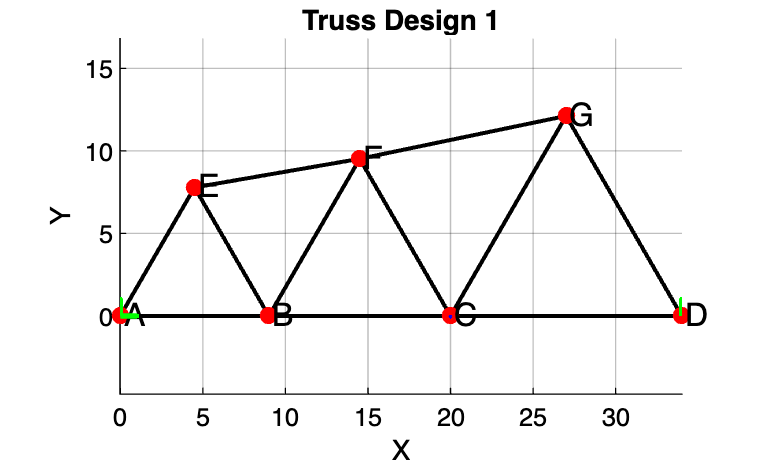

figure; hold on; grid on; axis equal;
set(gca, 'Color', 'w')
set(gcf, 'Color', 'w')
set(gca, 'XColor', 'k');       % x-axis black
set(gca, 'YColor', 'k');       % y-axis black
set(gca, 'ZColor', 'k');       % (safe for 3D)
% Plot connections
for i = 1:size(connections,1)
    n1 = connections(i,1);
    n2 = connections(i,2);
    
    p1 = nodes(n1).pos;
    p2 = nodes(n2).pos;
    
    plot([p1(1) p2(1)], [p1(2) p2(2)], 'k-', 'LineWidth', 1.5);
end

% Plot nodes + labels
for i = 1:length(nodes)
    x = nodes(i).pos(1);
    y = nodes(i).pos(2);
    
    plot(x, y, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
    text(x + 0.2, y + 0.2, nodes(i).label, 'FontSize', 12, 'Color', 'k');
    
    % External force (scaled for visibility)
    f = nodes(i).external_force;
    if norm(f) > 0
        quiver(x, y, f(1)*0.05, f(2)*0.05, 0, 'b', 'LineWidth', 1.5);
    end
    
    % Reactions (if any)
    R = nodes(i).reactions;
    if ~isempty(R)
        for k = 1:size(R,1)
            dir = R(k,:);
            if any(dir)
                quiver(x, y, dir(1), dir(2), 0, 'g', 'LineWidth', 2);
            end
        end
    end
end

title('Truss Design 1', 'Color', 'k');
xlabel('X'); ylabel('Y');